clear;

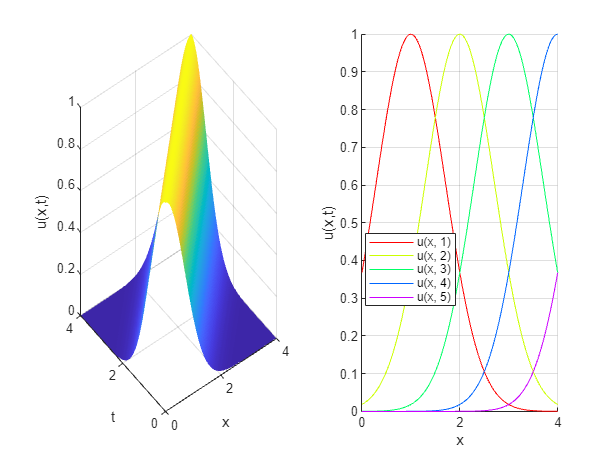

% u_t + u_x = 0
% u(x,0) = exp(-x^2)
% soln -> u(x,t) = f(x-t), for all t
% characteristics are linear

u = @(x,t) exp(-(x-t).^2);
N = 100;
xx = linspace(0, 4, N);
tt = linspace(0, 4, N);

PlotPDE(u, xx, tt, 5);

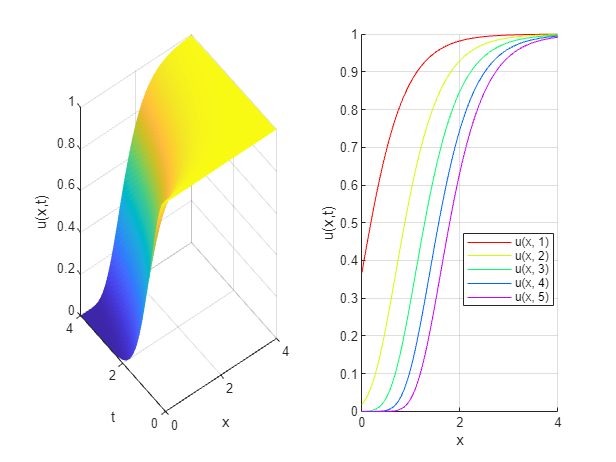

% u_t + t*u_x = 0
% u(x,0) = exp(-x^2)
% soln -> u(x,t) = f(exp(-x)t), for all t
% characteristics are exponential

u = @(x,t) exp(-t.^2.*exp(-2*x));
N = 100;
xx = linspace(0, 4, N);
tt = linspace(0, 4, N);

PlotPDE(u, xx, tt, 5);

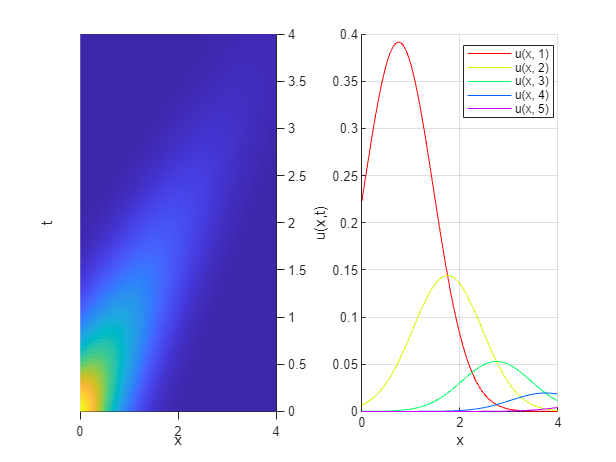

% u_t + u_x + u = 0
% u(x,0) = exp(-x^2)
% soln -> u(x,t) = f(x-t)*exp(-1/2*(x+t))
% characteristics are linear w/ exponential growth

u = @(x,t) exp(-(x-t).^2 - 1/2*(x+t));
N = 100;
xx = linspace(0, 4, N);
tt = linspace(0, 4, N);

PlotPDE(u, xx, tt, 5);